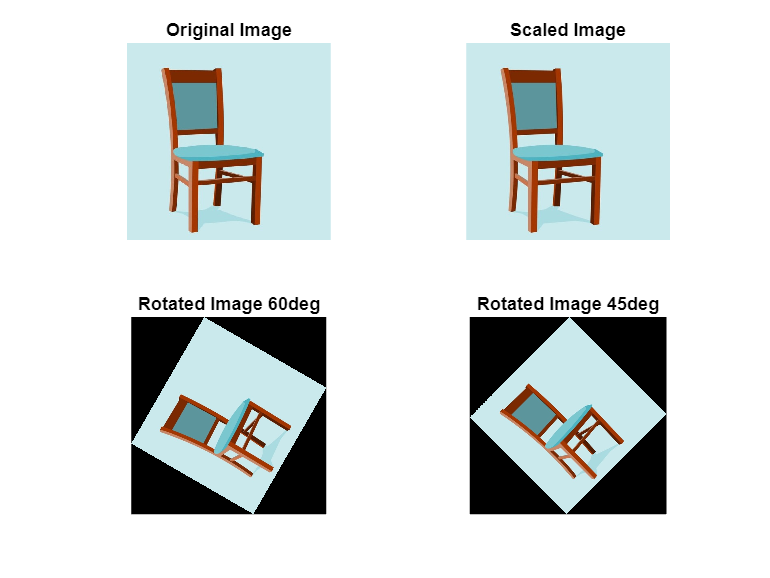

% Simulation and display of transformation 
% of image

clc;

% Scaling & Rotation

% Scaling (Resize)
s=input('Enter Scaling Factor ');

i=imread("original image.jpg");

subplot(2,2,1);
imshow(i);
title('Original Image');

j=imresize(i,s);
subplot(2,2,2);
imshow(j);
title('Scaled Image');

% Rotation
K=imrotate(j,60);
subplot(2,2,3);
imshow(K);
title('Rotated Image 60deg');

R=imrotate(j,45);
subplot(2,2,4);
imshow(R);
title('Rotated Image 45deg');

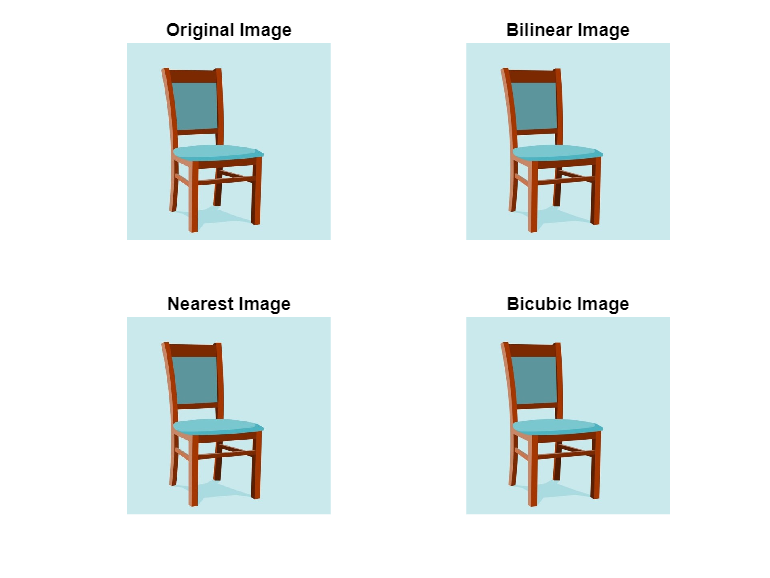


% Display the color image and its Resized images by different methods
% Display the color image


figure,
subplot(2,2,1);
imshow(i);
title('Original Image');

%Display Resized image by Bilinear method
B=imresize(i,5);
subplot(2,2,2);
imshow(B);
title('Bilinear Image');

%Display Resized image by Nearest method
C=imresize(i,5,'nearest');
subplot(2,2,3);
imshow(C);
title('Nearest Image');

%Display Resized image by Bicubic method
D=imresize(i,5,'Bicubic');
subplot(2,2,4);
imshow(D);
title('Bicubic Image');